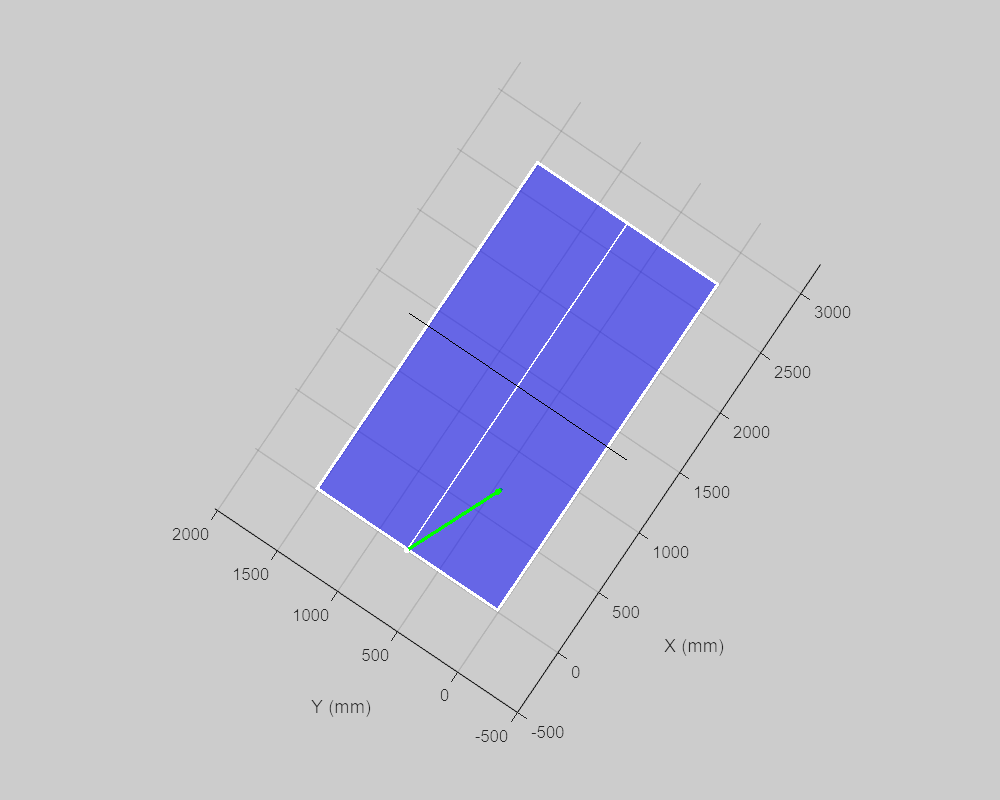

% Constantes de la simulación
ball_mass = 2.7;      % masa de la pelota en gramos
ball_radius = 20.25;  % radio de la pelota en mm
ball_rot_inertia = 2/3*ball_mass*ball_radius^2; % inercia rotacional de la pelota (g mm^2)
table_restitution = 0.77; % coeficiente de restitución al chocar con la mesa
net_restitution = 0.5; % coeficiente de restitución al chocar con la red
drag = 2.7;           % resistencia aerodinámica en mN/(mm/s)
rot_drag = 350.0;     % resistencia al giro en mN mm/[rad/s]
magnus = 0.01;        % fuerza de Magnus en mN/(mm/s^2)
table_friction = 0.25;% proporción de la velocidad angular transformada en velocidad lineal tras el rebote
table_length = 2740;  % longitud de la mesa en mm
table_width = 1525;   % ancho de la mesa en mm
table_height = 760;   % altura de la mesa en mm
net_height = 152.5;   % altura de la red en mm
net_extra = 180;      % espacio adicional a los lados de la red en mm
g = 9800;             % aceleración de gravedad en mm/s^2
animate = true;       % indica si la animación se debe mostrar
plot_period = 5;      % periodo de muestreo para la animación
yaw = -45;            % ángulo de giro de la vista 3D
pitch = 23,5;         % ángulo de elevación de la vista 3D
dt = 0.005;           % intervalo de tiempo para la simulación en segundos
t = 0:dt:1.5;         % vector de tiempo

% Inicialización de matrices para posición, velocidad, aceleración, rotación y sus derivadas
x = zeros(3,length(t));
v = zeros(3,length(t));
a = zeros(3,length(t));
theta = zeros(3,length(t));
omega = zeros(3,length(t));
alpha = zeros(3,length(t));

% Condiciones iniciales
x(:,1) = [0; table_width*4/8; table_height+2*net_height]; % posición inicial
v(:,1) = [7000; -3000; -3000];           % velocidad inicial [7000; 0; -1500] es un servicio corto con efecto inverso
omega(:,1) = [0; 0; 75]*2*pi;         % velocidad angular inicial

% Configuración de la figura para la animación
fig = figure(); 
fig.Position(1:2) = [400, 400];
fig.Position(3:4) = [800, 640];
plotTable(x(:,1),v(:,1),a(:,1),theta(:,1),omega(:,1),alpha(:,1), yaw, pitch)

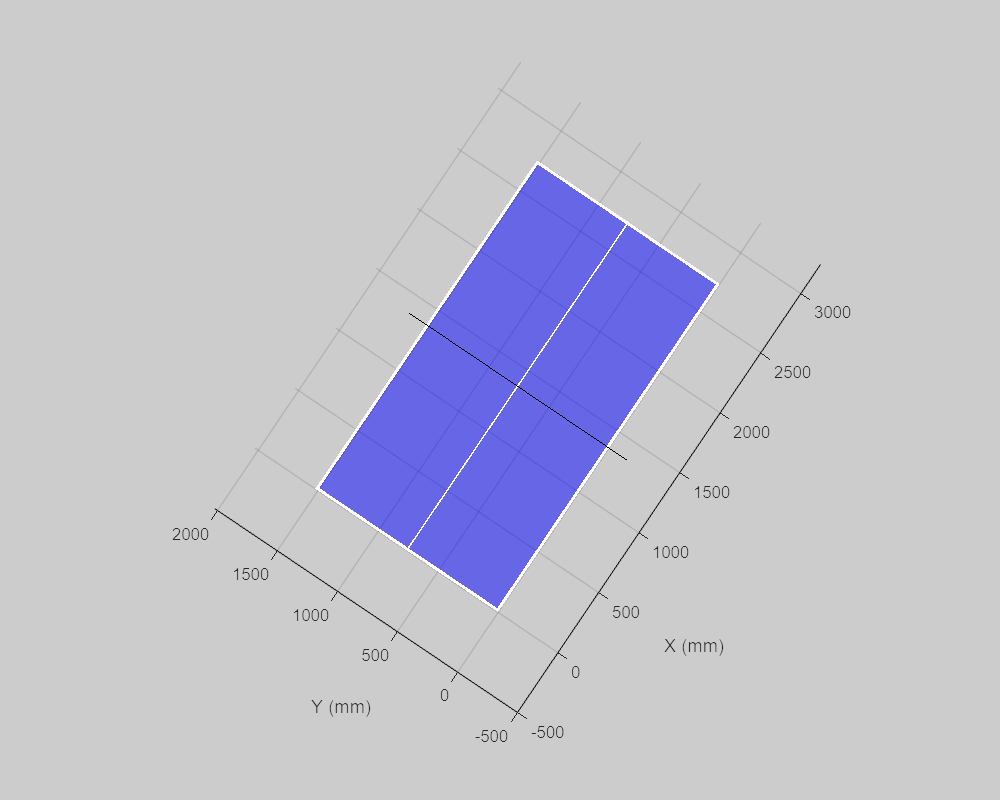


% Bucle de simulación
for k = 2:length(t)
    % Cálculo de las fuerzas aplicadas a la pelota
    F = g*ball_mass*[0; 0; -1] - drag*v(:,k-1) + magnus*cross(omega(:,k-1),v(:,k-1));
    a(:,k) = F/ball_mass;                       % aceleración actual
    v(:,k) = v(:,k-1) + a(:,k)*dt;              % velocidad actual
    x(:,k) = x(:,k-1) + v(:,k)*dt;              % posición actual
    
    % Cálculo del torque y aceleración angular
    tau = - rot_drag*omega(:,k-1);              % torque debido a la resistencia rotacional
    alpha(:,k) = tau/ball_rot_inertia;          % aceleración angular actual
    omega(:,k) = omega(:,k-1) + alpha(:,k)*dt;  % velocidad angular actual
    theta(:,k) = theta(:,k-1) + omega(:,k)*dt;  % ángulo rotacional acumulado

    % Rebote en la mesa
    if((x(1,k)>0) && (x(1,k)<table_length) && (x(2,k)>0) && (x(2,k)<table_width) && x(3,k)< table_height+ball_radius)
        x(3,k) = table_height+ball_radius; % corrige la posición de la pelota para que no penetre la mesa
        delta_lin_rot = cross(omega(:,k),[0;0;ball_radius])-[v(1:2,k); 0];
        v(:,k) = v(:,k) + table_friction*delta_lin_rot;
        omega(:,k) = omega(:,k) + table_friction*cross(delta_lin_rot,[0;0;1])/ball_radius;
        v(3,k) = -table_restitution*v(3,k); % invierte y reduce la velocidad vertical tras el rebote
    end

    % Colisión con la red (requiere mejora)
    if((x(1,k)>=table_length/2-ball_radius) && (x(1,k)<=table_length/2+ball_radius) &&...
       (x(2,k)>-net_extra) && (x(2,k)<table_width+net_extra) &&...
       (x(3,k)> table_height+ball_radius) && (x(3,k)< table_height+net_height+ball_radius))
        omega(:,k) = net_restitution*omega(:,k); % amortigua la velocidad angular
        v(1,k) = -net_restitution*v(1,k);        % amortigua y refleja la velocidad en el eje x
    end

    % Animación de la simulación
    if(animate == true && mod(k,plot_period) == 0) 
        plotTable(x(:,k),v(:,k),a(:,k),theta(:,k),omega(:,k),alpha(:,k), yaw, pitch)
        pause(0) % pausa breve para la animación
    end
end

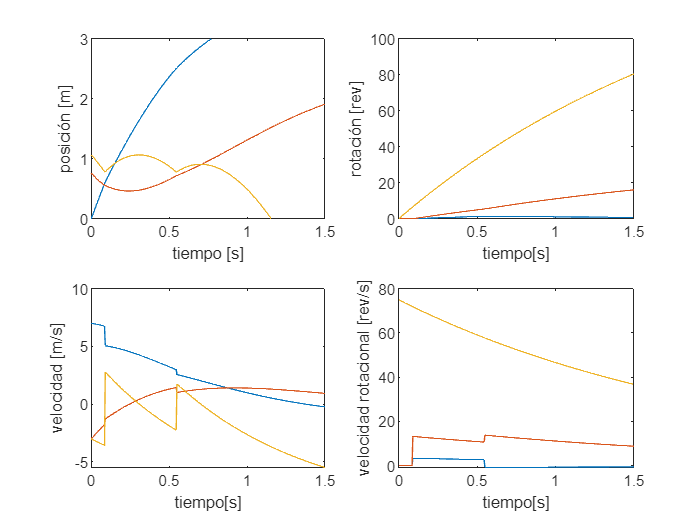


% Gráficas de posición, velocidad, rotación y velocidad angular
figure()
subplot(2,2,1)
plot(t,x/1000)
xlabel('tiempo [s]')
ylabel('posición [m]')
ylim([0,3])
subplot(2,2,3)
plot(t,v/1000)
xlabel('tiempo[s]')
ylabel('velocidad [m/s]')
subplot(2,2,2)
plot(t,theta/(2*pi))
xlabel('tiempo[s]')
ylabel('rotación [rev]')
subplot(2,2,4)
plot(t,omega/(2*pi))
xlabel('tiempo[s]')
ylabel('velocidad rotacional [rev/s]')

function plotTable(x,v,a,theta,omega,alpha,yaw, pitch)
% Define the dimensions of the table tennis table
table_length = 2740;  % mm
table_width = 1525;   % mm
table_height = 760;   % mm

net_height = 152.5;   % mm
net_extra = 180;      % mm
% Plot the table surface
[X, Y] = meshgrid([0, table_length], [0, table_width]);
Z = ones(size(X)) * table_height;
surf(X, Y, Z, 'FaceColor', 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on;
% Plot the white lines
[X, Y] = meshgrid([0, 20], [0, table_width]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([table_length-20, table_length], [0, table_width]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([0, table_length], [0, 20]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([0, table_length], [table_width-20, table_width]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[X, Y] = meshgrid([0, table_length], [table_width/2-5, table_width/2+5]);
Z = ones(size(X)) * table_height+0.1;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');

% Plot the net
[Y, Z] = meshgrid([-net_extra+30, table_width+net_extra-30], [table_height+130, table_height+net_height]);
X = ones(size(Z)) * table_length/2;
surf(X, Y, Z, 'FaceColor', 'w', 'EdgeColor', 'none');
[Y, Z] = meshgrid([-net_extra, -net_extra+30], [table_height, table_height+net_height]);
X = ones(size(Z)) * table_length/2;
surf(X, Y, Z, 'FaceColor', 'k', 'EdgeColor', 'none');
[Y, Z] = meshgrid([table_width+net_extra-30, table_width+net_extra], [table_height, table_height+net_height]);
X = ones(size(Z)) * table_length/2;
surf(X, Y, Z, 'FaceColor', 'k', 'EdgeColor', 'none');
net_square_side = 20;
net_lines_v = -net_extra+30:net_square_side:table_width+net_extra-30;
net_lines_h = table_height:net_square_side:table_height+130;
for i = 1:length(net_lines_h)
    plot3(table_length/2*ones(1,2), [-net_extra+30, table_width+net_extra-30], [net_lines_h(i), net_lines_h(i)],'k','LineWidth',0.5)
end
for i = 1:length(net_lines_v)
    plot3(table_length/2*ones(1,2), [net_lines_v(i), net_lines_v(i)], [table_height, table_height+130],'k','LineWidth',0.5)
end

% Plot the ball
radius = 20.25;
[X, Y, Z] = sphere(25);
surf(X*radius + x(1), Y*radius + x(2), Z*radius + x(3), 'FaceColor', 'w', 'FaceAlpha', 1, 'EdgeColor','none');

% Plot the ball velocity and acceleration
quiver3(x(1),x(2),x(3),v(1),v(2),v(3),10/98,'LineWidth',2,'Color','g')
quiver3(x(1),x(2),x(3),a(1),a(2),a(3),1/49,'LineWidth',2,'Color','c')

% Plot the ball orientation, angular velocity, and angular acceleration
quiver3(x(1),x(2),x(3),omega(1),omega(2),omega(3),1,'LineWidth',2,'Color','r')
%quiver3(x(1),x(2),x(3),alpha(1),alpha(2),alpha(3),1,'LineWidth',2,'Color','m')

% Set plot properties
axis equal;
view([yaw pitch])
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Z (mm)');
set(gcf, 'Color', [0.8, 0.8, 0.8]); % Set the color to a light gray
ax = gca;
ax.Color = 'none';
grid on;
xlim([-500, table_length + 500])
ylim([-500, table_width  + 500])
zlim([0, 1500])
hold off;
end